## 2 Gradient Descent Logistic Regression

###  read data

cd 'yalefaces'
files = ls;    % list all files
X = zeros(154,1600);
y = zeros(154,1);
k=0;
for ii=1:length(files)  % channel
    if startsWith(files(ii),'s') % get all files start with 's' 
        k=k+1;
        file = files(ii,:);
        title= split(file,{'.',' '});
        score= str2double(regexprep(title{1},['^' 'subject'],'')); % strip prefix 'subject'
        y(k)=score;
        
        fileArray = imread(file);
        fileArrayReduced = imresize(fileArray,[40 40]); % resize
        X(k,:) = fileArrayReduced(:);         % transfer to 1-D array
    end
end
cd ../

### Data preperation

% randomize the data
rng(20)  % random state
idx = randperm(154);
X = X(idx,:);
y = y(idx);

% number of classes
[~,GR] = groupcounts(y);
K = length(GR);

% split the train adn test dataset
ratio  = 2/3;
X_train = [];
y_train = [];
X_test = [];
y_test = [];   

% devide the data class-wise to ensure train adntest has close/identical priors
for ii=1:K
    idx_class_ii = find(y == GR(ii)); % find the idx for class GR(ii)
    N_class_ii = length(idx_class_ii);
    split_num = round(N_class_ii*ratio);
    X_train = [X_train;X(idx_class_ii(1:split_num),:)];
    y_train = [y_train;y(idx_class_ii(1:split_num))];
    X_test = [X_test;X(idx_class_ii(split_num+1:N_class_ii),:)];
    y_test = [y_test;y(idx_class_ii(split_num+1:N_class_ii))];    
end

% check the prior for each class in train and test set
[GC_train,GR_train] = groupcounts(y_train);
[GC_test,GR_test] = groupcounts(y_test);
% plot(GR_train,GC_train/Num_train,'k*')
% hold on
% plot(GR_test,GC_test/(size(X,1)-Num_train),'bs')
% xlabel('class #')
% ylabel('the prior')
% legend('Train','Test')
% hold off

% standerize the dataset and add bias
mean_train = mean(X_train);
std_train = std(X_train);
X_train_S = (X_train-mean_train)./std_train; % standerdize
X_train_S(:,end+1)=1; % add bias in the end
X_test_S = (X_test - mean_train)./std_train;
X_test_S(:,end+1) = 1; % add bias for test data set
[Num_train,D] = size(X_train_S); % size of train dataset

% Verterize labels
Y_train = binary_vector(y_train,GR);
Y_test = binary_vector(y_test,GR);

### Trains an artificial neural network using the training data

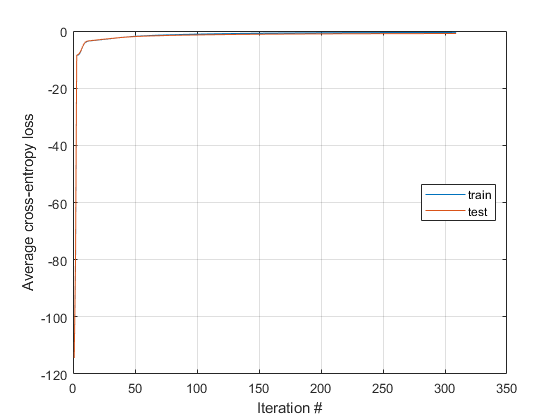

%  parameters
rate = 0.75; % learning rate
alpha =8e-3; % blending factor

% initialization
M = [100]; % the dimension of hidden layers
seed = 61;

[beta,theta,~] = ANN(X_train_S,Y_train,X_test_S,Y_test,M,rate,alpha,seed,1);

% % compuate the accuracy for test dataset
L2 = norm(diag(0.5*(theta'*theta)))

L2 = 18.3833

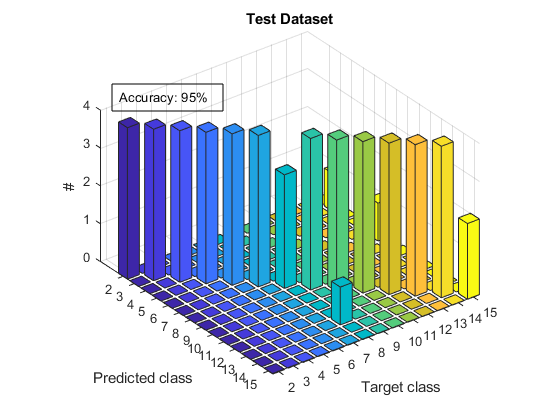

CM_test = output(X_test_S,beta,theta,Y_test,GR,1,'Test Dataset');

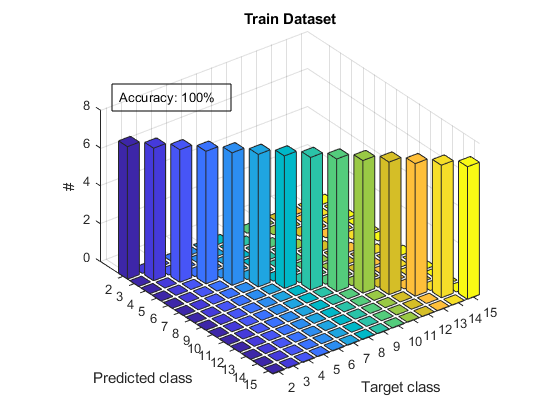

CM_train = output(X_train_S,beta,theta,Y_train,GR,1,'Train Dataset');

## 3 Multi-Layer ANN

%  parameters
rate =0.75; % learning rate
alpha =2e-4; % blending factor

% initialization
M = [600,50]; % the dimension of hidden layers
seed = 120;

display('Q3')

Q3


[beta,theta,N_iteration] = ANN(X_train_S,Y_train,X_test_S,Y_test,M,rate,alpha,seed,0);
% compuate the accuracy for test dataset
CM_test = output(X_test_S,beta,theta,Y_test,GR,0,'Test Dataset');
CM_train = output(X_train_S,beta,theta,Y_train,GR,0,'Train Dataset');

% Display results

% write to the tavle
% results_table = table();
varNames = {'Hidden_layers_Vector','Learning_rate','L2_regularization_coefficient','Random_seed','Number_Of_Iteration','Train_accuracy','Test_accuracy'};
temp_table = table({M},rate,alpha,seed,N_iteration,CM_train(end,end),CM_test(end,end),'VariableNames',varNames)

temp_table = 1×7 table
    Hidden_layers_Vector    Learning_rate    L2_regularization_coefficient    Random_seed    Number_Of_Iteration    Train_accuracy    Test_accuracy
    ____________________    _____________    _____________________________    ___________    ___________________    ______________    _____________

        {1×2 double}            0.75                    0.0002                    120               1042                  1              0.92857   


% results_table = [results_table;temp_table]
% user_judgement = input('Save this run or not? Y/N:',"s")
% if strcmpi(user_judgement,'Y')
%     results_table = [results_table;temp_table]
% end


function [beta,theta,k] = ANN(X_train_S,Y_train,X_test_S,Y_test,M,rate,alpha,seed,plot_or_not)
    % parameters
    rng(seed)
    K = size(Y_train,2);
    D = size(X_train_S,2);
    Ds = [D,M];
    
    % initialization
    beta= cell(size(M,2),1); % weights of the 
    for ii=1:size(M,2)
        beta{ii} = rand(Ds(ii),Ds(ii+1));  % initialize the betas
    end
    theta = rand(Ds(end),K);
    J_train=[];J_test=[];
    J_diff = 1;
    k=0;    
    % [Y_hat,H] = Y_prediction(X_train_S,beta,theta);
    %  dJ_beta = X_train_S'* ( ((Y_train-Y_hat)*theta').* (H.*(1-H)))/1601 + alpha*beta
     [Y_hat,Hs] = Y_prediction(X_train_S,beta,theta);    
    while J_diff>1e-3
        k=k+1;
        [J_train(k), dJ_beta, dJ_theta] = loglikelihood(X_train_S,beta,theta,Y_train,alpha);    
        [J_test(k),~,~] = loglikelihood(X_test_S,beta,theta,Y_test,alpha); % J for test dataset
        if k==1
            J_diff = 1;
        else
            J_diff = abs((J_train(k)-J_train(k-1))/J_train(k-1));
        end
            
        theta = theta + rate*dJ_theta;
        beta = cellfun(@plus,beta,cellfun(@(b) rate*b,dJ_beta,'UniformOutput',false),'Un',0);
    end
    
    % plot the objective function against the iteration numbers
    if plot_or_not
        plot(1:k,J_train)
        hold on
        plot(1:k,J_test)
        hold off
        grid on
        xlabel('Iteration #')
        ylabel('Average cross-entropy loss')
        legend('train','test')
        legend('Location','east')
    end

%     output(X_test_S,beta,theta,Y_test,GR,0)
end


function [Y_hat,Hs] = Y_prediction(X_data,beta,theta)
    N_H = size(beta,1); % the number of hidden layers
    Hs = cell(N_H+1,1);
    Hs{1} = X_data;
    for jj=1:N_H
        net_H = Hs{jj}*beta{jj};           
        % normalize by max
%          for ii=1:size(net_H,1)
%                 if nnz(net_H(ii,:))>0  % hande large number pass to exp
%                     net_H(ii,:) = net_H(ii,:)/max(abs(net_H(ii,:)));
%                 end
%          end 
         
         % standize
        mean_h = mean(net_H);
        std_h = std(net_H);
        net_H = (net_H-mean_h)./std_h; % standerdize
        H = 1./(1+exp(-net_H));
%         H(:,end+1)=1;
        Hs{jj+1}=H;
    end
%     mean_h = mean(H);
%     std_h = std(H);
%     H = (H-mean_h)./std_h; % standerdize
%     H(:,end+1)=1; % add bias in the end

    net_O = Hs{N_H+1}*theta;
%         mean_h = mean(net_O);
%         std_h = std(net_O);
%         net_O = (net_O-mean_h)./std_h; % standerdize
%  for ii=1:size(net_O,1)
%         if nnz(net_O(ii,:))==0  % hande large number pass to exp
%             
%         else
%             net_O(ii,:) = net_O(ii,:)/max(abs(net_O(ii,:)));
%         end
%  end

    Y_hat = 1./(1+exp(-net_O));

end    

function [J,dJ_beta,dJ_theta] = loglikelihood(X_data,beta,theta,Y,alpha)
   [Y_hat,Hs] = Y_prediction(X_data,beta,theta);    
    % processing small/large probablity
    idx_small = Y_hat<0.0001; Y_hat(idx_small)=0.0001;
    idx_large = Y_hat>1-0.0001;Y_hat(idx_large)=1-0.0001;
    
    
    % calculate the objective function as log likelihood
    [N,K] = size(Y);
    J=0;
    for ii=1:N
        for kk=1:K
            J = J + Y(ii,kk)*log(Y_hat(ii,kk))+ (1-Y(ii,kk))*log(1-Y_hat(ii,kk));
        end
    end
    J = J/N; % average the objective function
   
    % gradient of beta
    N_H = size(beta,1); % size of Betas, equal to 1 plus size of hidden layers
    dJ_beta = cell(N_H,1);
    for jj=1:N_H
        temp = ((Y-Y_hat)*theta'.* (Hs{N_H+1}.*(1-Hs{N_H+1})));
        for kk  = N_H-1:-1:jj
            temp = temp*beta{kk+1}'.* (Hs{kk+1}.*(1-Hs{kk+1}));
        end
        dJ_beta{jj} = Hs{jj}'*temp/N - alpha*beta{jj}; 
    end
    % gradient of theta
    dJ_theta = Hs{N_H+1}'*(Y-Y_hat)/N - alpha*theta; 
    
end

function Y_b = binary_vector(y,GR)
% vertorize the 
    Y_b = zeros(size(y,1),size(GR,1));
    for ii = 1:size(y,1)
        Y_b(ii,:) = GR==y(ii);
    end
end

function M = confusionMatrix(y_p,y_b)
    M = zeros(size(y_b,2)+1);
    for ii=1:size(y_p,1)
        y_p_b(ii,:) = y_p(ii,:)==max(y_p(ii,:));% choose a class for predicted value
        idx = find(y_b(ii,:)==1); % true class
        if y_p_b(ii,:)==y_b(ii,:)
            M(idx,idx) = M(idx,idx) +1;
        else
             idx_p = find(y_p_b(ii,:)==1);
             M(idx_p,idx) = M(idx_p,idx) +1;
        end  
    end
    % M = M/size(y_b,1); % get the percentage
    for jj=1:size(y_b,2)
        M(jj,end) = M(jj,jj)/sum(M(jj,1:end-1));
        M(end,jj) = M(jj,jj)/sum(M(1:end-1,jj));
    end
    M(end,end) = sum(diag(M(1:end-1,1:end-1)))/size(y_b,1);   
end

function CM = output(X_test_S,beta,theta,Y_test,GR,plot_or_not,title_string)
    [Y_test_P,~] = Y_prediction(X_test_S,beta,theta);
    CM = confusionMatrix(Y_test_P,Y_test);
    Overall_acccuracy = CM(end,end);
    
    if plot_or_not
        bar3(GR,CM(1:end-1,1:end-1))
        set(gca,'XTickLabel',GR)
        xlabel('Target class')
        ylabel('Predicted class')
        zlabel('#')
        title(title_string)
        annotation('textbox',[.2 .5 .3 .3],'String',sprintf('Accuracy: %.0f%%',Overall_acccuracy*100),'FitBoxToText','on');
    end
%     redundant = sum(sum(CM(1:end-1,1:end-1)))-size(Y_test,1);
    
    
    
%     [Y_train_P,~] = Y_prediction(X_train_S,beta,theta);
%     CM_train = confusionMatrix(Y_train_P,Y_train);
%     Overall_acccuracy_train = CM_train(end,end)
end